Ejercicios raíces

5.7 Determine the roots of f (x) = −12 − 21*x + 18*x^2 − 2.75*x^3 graphically. In addition, determine the first root of the function with bisection (linear interpolation and Newton-Raphson)

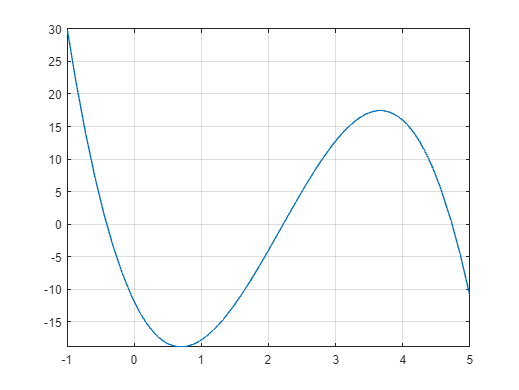

f = @(x) -12-21*x+18*x.^2-2.75*x.^3;
fplot(f,[-1 5]);
grid on;

This plot indicates that roots are located at about –0.4, 2.25 and 4.7. La primera raíz está en [-1,0].


[x1(1),i1(1)] = R1_Biseccion(f,-1,0);
[x1(2),i1(2)] = R2_Interpolacion(f,-1,0);
[x1(3),i1(3)] = R3_Secante(f,1,2);
[x1(4),i1(4)] = R4_rfNewton(f,-.5)

x1 =    -0.4147   -0.4147    2.2198   -0.4147


i1 =     54    13     6     5





[x2(1),i2(1)]  = R1_Biseccion(f,2,2.5);
[x2(2),i2(2)]  = R2_Interpolacion(f,2,2.5);
[x2(3),i2(3)]  = R3_Secante(f,2,3);
[x2(4),i2(4)]  = R4_rfNewton(f,2.5)

x2 =     2.2198    2.2198    2.2198    2.2198


i2 =     50     5     6     5






[x3(1),i3(1)] = R1_Biseccion(f,4.6,4.8);
[x3(2),i3(2)] = R2_Interpolacion(f,4.6,4.8);
[x3(3),i3(3)] = R3_Secante(f,4,5);
[x3(4),i3(4)] = R4_rfNewton(f,4.8)

x3 =     4.7403    4.7403    4.7403    4.7403


i3 =     45     7     8     5


5.8 Locate the first nontrivial root of sin(x) = x^2 where x is in radians. Use a graphical technique and a numerical algorithm..

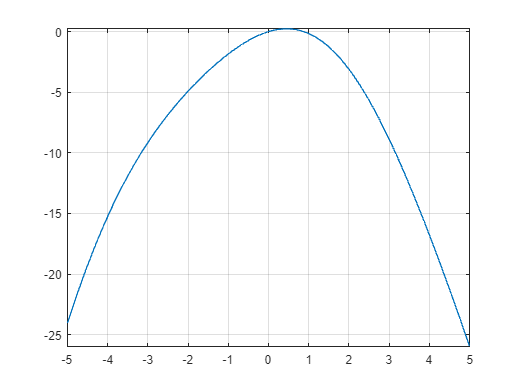


f = @(x) sin(x)-x.^2;
fplot(f);
grid on;




[x4(1),i4(1)] = R1_Biseccion(f,.5,1.5);
[x4(2),i4(2)] = R2_Interpolacion(f,.5,1.5);
[x4(3),i4(3)] = R3_Secante(f,1,2);
[x4(4),i4(4)] = R4_rfNewton(f,1)

x4 =     0.8767    0.8767    0.8767    0.8767


i4 =     52    33     8     6


5.9 Determine the positive real root of ln(x^2) = 0.7 (a) graphically, (b) using a numerical method, with initial guess in xl = 0.5 and xu = 2

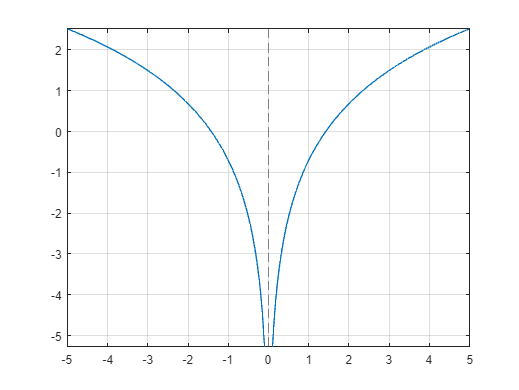

f = @(x) log(x.^2) - 0.7;
fplot(f);
grid on;




[x5(1),i5(1)] = R1_Biseccion(f,.5,2);
[x5(2),i5(2)] = R2_Interpolacion(f,.5,2);
[x5(3),i5(3)] = R3_Secante(f,1,2);
[x5(4),i5(4)] = R4_rfNewton(f,1)

x5 =     1.4191    1.4191    1.4191    1.4191


i5 =     53    37     8     6





[x6(1),i6(1)] = R1_Biseccion(f,-.5,-2);
[x6(2),i6(2)] = R2_Interpolacion(f,-.5,-2);
[x6(3),i6(3)] = R3_Secante(f,-1,-2);
[x6(4),i6(4)] = R4_rfNewton(f,-1)

x6 =    -1.4191   -1.4191   -1.4191   -1.4191


i6 =     53    37     8     6


Escribe aquí las funciones bisección, interpolación lineal y Newton-Raphson.